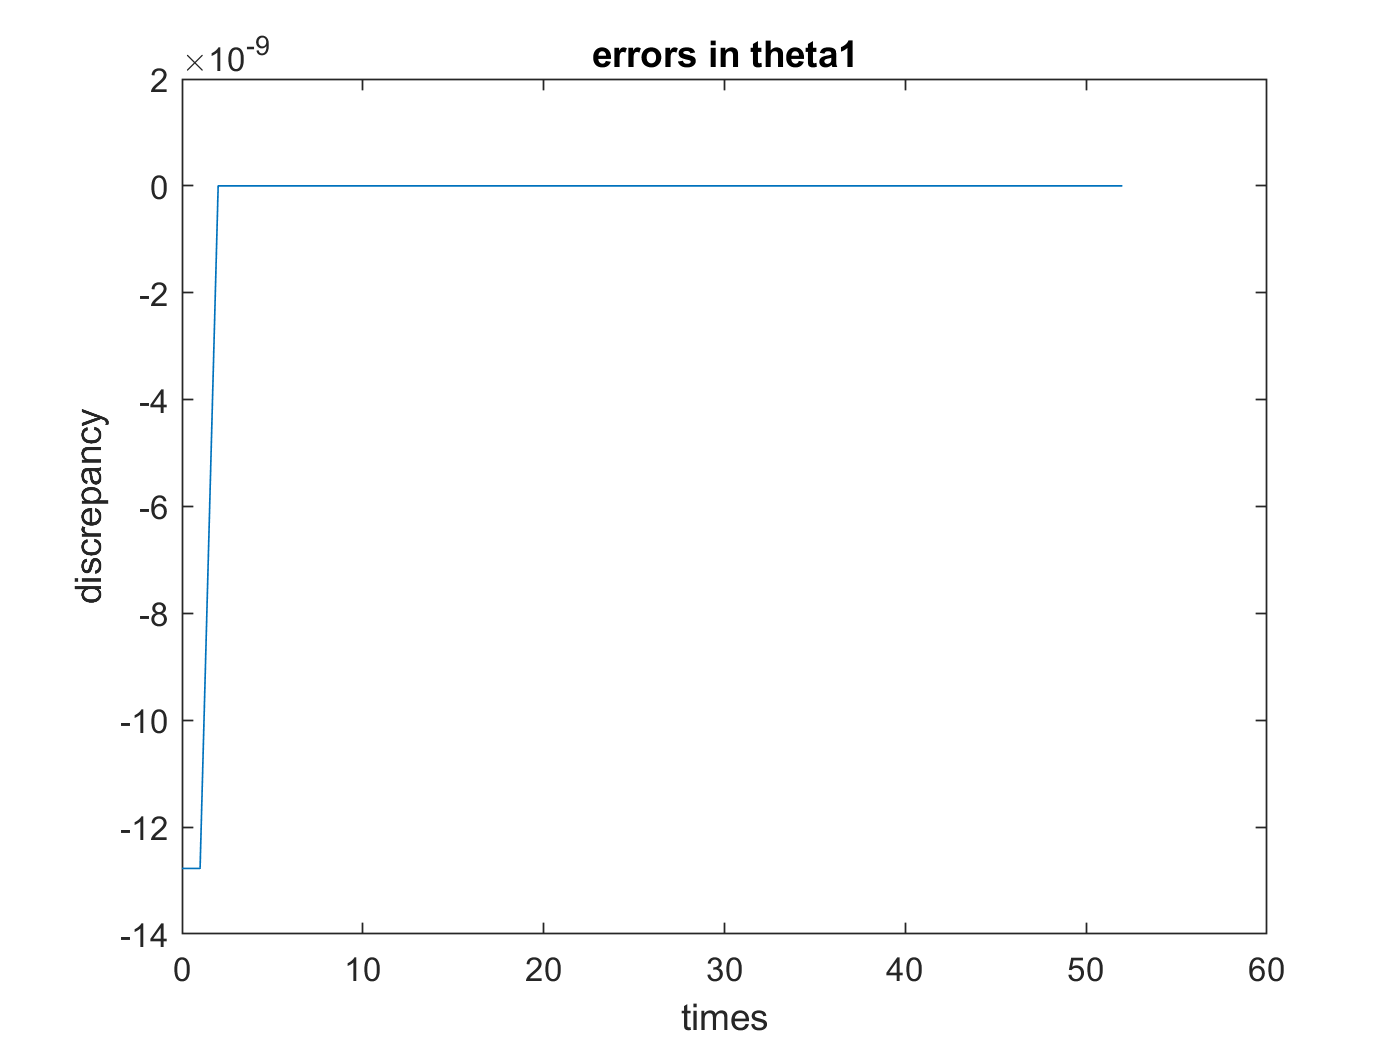

% syms theta1 alpha1 a1 d1
% T_0_1 = [cos(theta1), -sin(theta1), 0, a1*cos(theta1);
% sin(theta1), cos(theta1), 0, a1*sin(theta1);
% 0, 0, 1, 0;
% 0, 0, 0, 1]
% syms theta2 alpha2 a2 d2
% T_1_2 = [cos(theta2), sin(theta2), 0, a2*cos(theta2);
% sin(theta2), -cos(theta2), 0, a2*sin(theta2);
% 0, 0, -1, 0;
% 0, 0, 0, 1]
% syms theta3 alpha3 a3 d3
% T_2_3 = [1, 0, 0, 0;
% 0, 1, 0, 0;
% 0, 0, 1, d3;
% 0, 0, 0, 1]
% syms theta4 alpha4 a4 d4
% T_3_4 = [cos(theta4), -sin(theta4), 0, 0;
% sin(theta4), cos(theta4), 0, 0;
% 0, 0, 1, d4;
% 0, 0, 0, 1]
% T_0_4 = T_0_1*T_1_2*T_2_3*T_3_4;
originalM = zeros(4,53);
inverseKResult = zeros(4,53);
T = zeros(4,4);
temp1 = zeros(1,53);
temp2 = zeros(1,53);
i = 1;
while i < 53
theta1 = qd(i,1);
theta2 = qd(i,2);
theta4 = qd(i,4);
d3 = qd(i,3);
d4 = 0.1;
a1 = 0.4;
a2 = 0.3;
T = [ cos(theta1 + theta2 - theta4),  sin(theta1 + theta2 - theta4),  0, a2*cos(theta1 + theta2) + a1*cos(theta1);
      sin(theta1 + theta2 - theta4), -cos(theta1 + theta2 - theta4), 0, a2*sin(theta1 + theta2) + a1*sin(theta1);
      0, 0, -1,-d3-d4;
      0, 0,  0, 1];

originalM(1,i) = theta1;
originalM(2,i) = theta2;
originalM(3,i) = theta4;
originalM(4,i) = d3;

x = T(1,4); y = T(2,4); z = T(3,4); beta = theta1 + theta2 - theta4;
T(1,1);
cos_theta2 = (x^2+y^2-a2^2-a1^2)/(2*a1*a2);
sin_theta2 = sqrt(1-cos_theta2^2);
theta2 = atan(sin_theta2/cos_theta2);
k1 = a1 + a2*cos(theta2);
k2 = a2*sin(theta2);

temp1(1,i) = y;
temp2(1,i) = beta;
if y/x < 0
    theta1 = pi + atan(y/x) - atan(k2/k1);
else
    theta1 = atan(y/x) - atan(k2/k1);
end 

theta4 = theta1 + theta2 - beta ;
d3 = -z - 0.1;
inverseKResult(1,i) = theta1;
inverseKResult(2,i) = theta2;
inverseKResult(3,i) = theta4;
inverseKResult(4,i) = d3;

i = i+1;
end

error = inverseKResult - originalM;
figure(1);
x = 0:1:52;
plot(x,error(1,:))
title("errors in theta1");
xlabel("times");
ylabel("discrepancy");

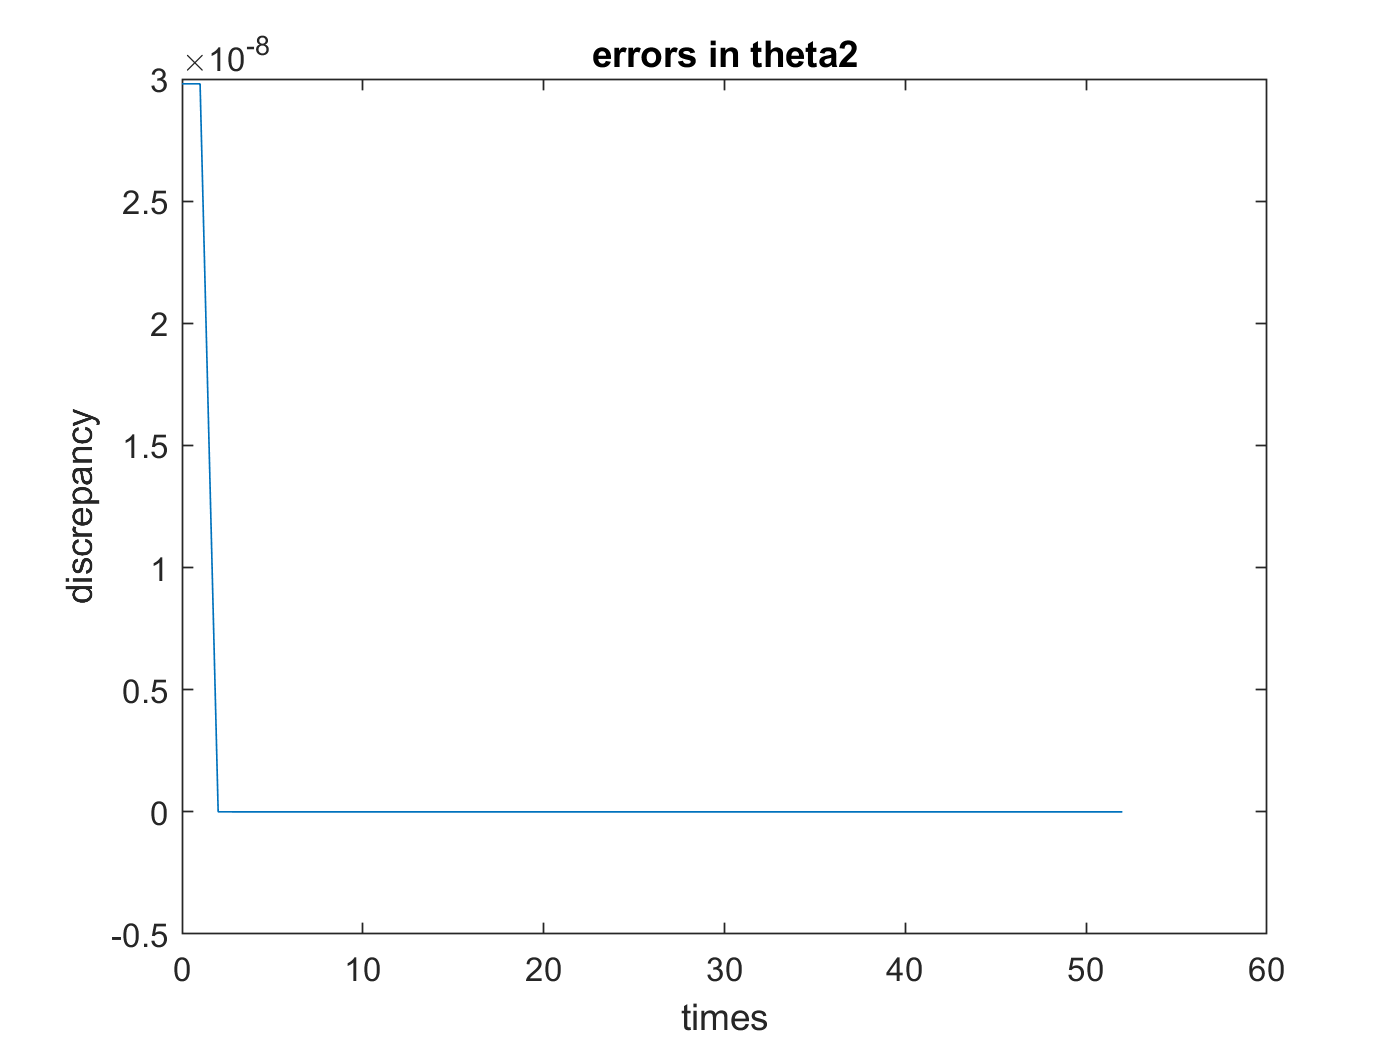


figure(2);
plot(x,error(2,:))
title("errors in theta2");
xlabel("times");
ylabel("discrepancy");

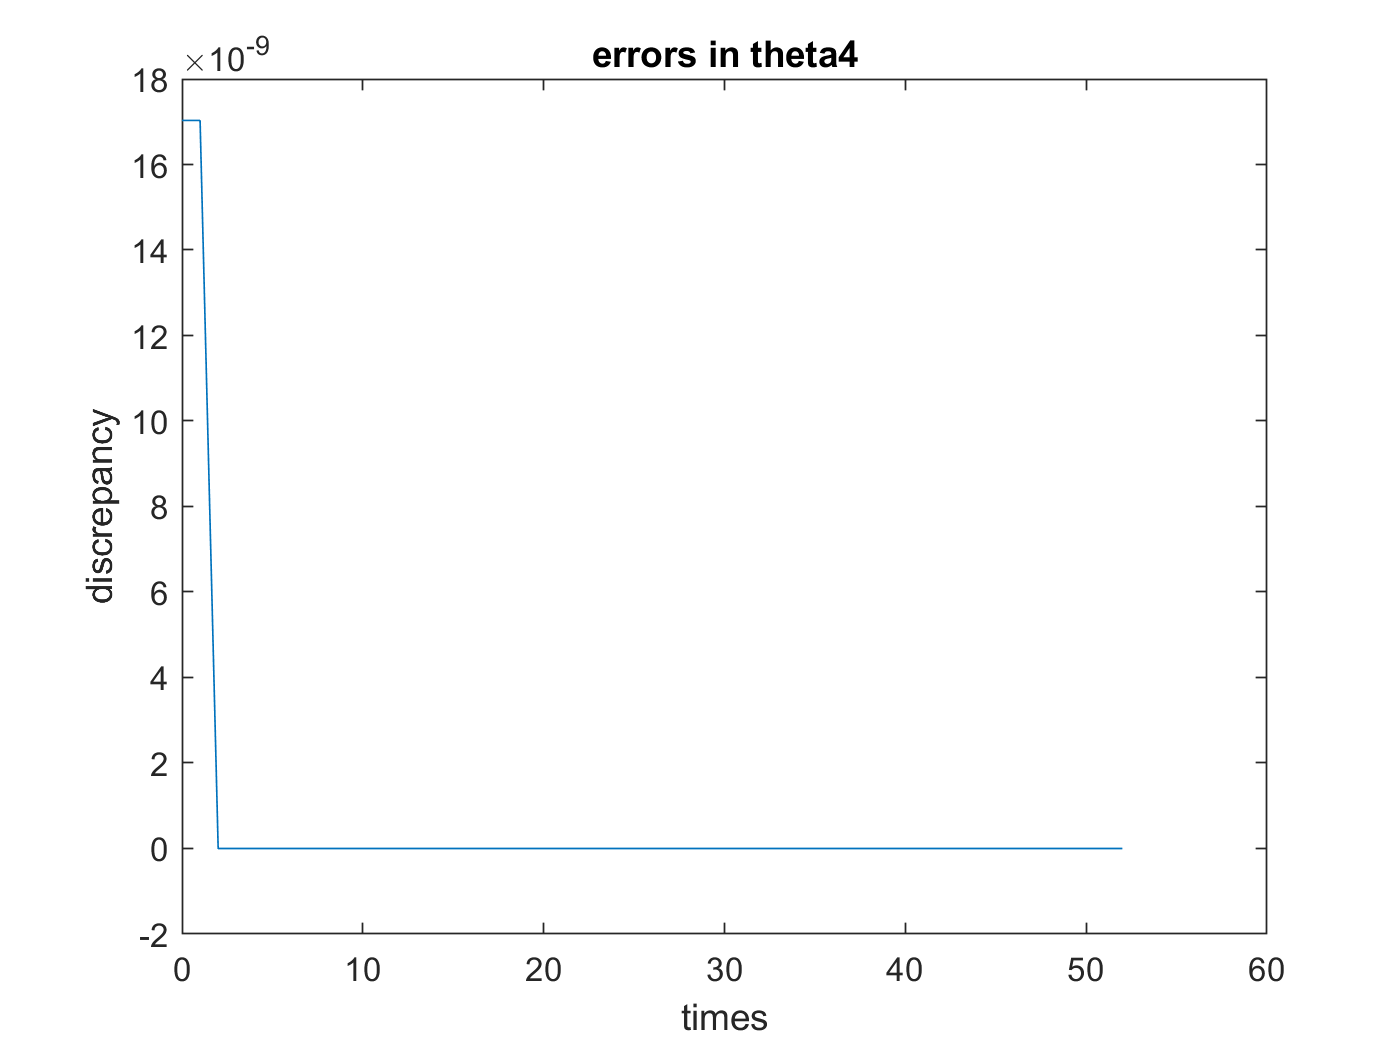


figure(3);
plot(x,error(3,:))
title("errors in theta4");
xlabel("times");
ylabel("discrepancy");

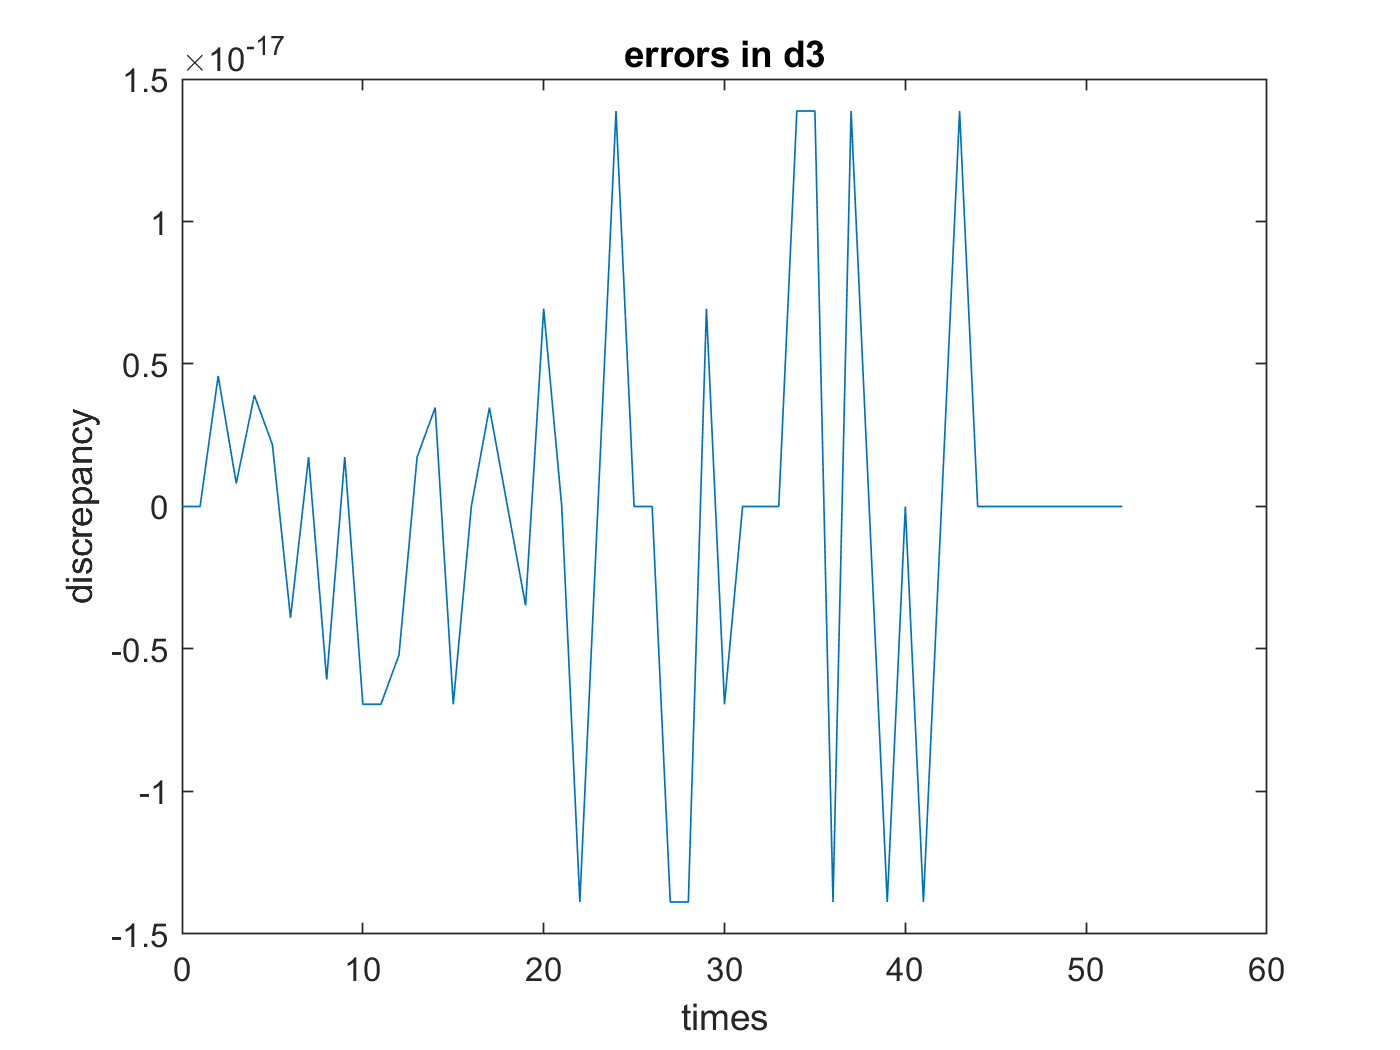


figure(4);
plot(x,error(4,:))
title("errors in d3");
xlabel("times");
ylabel("discrepancy");